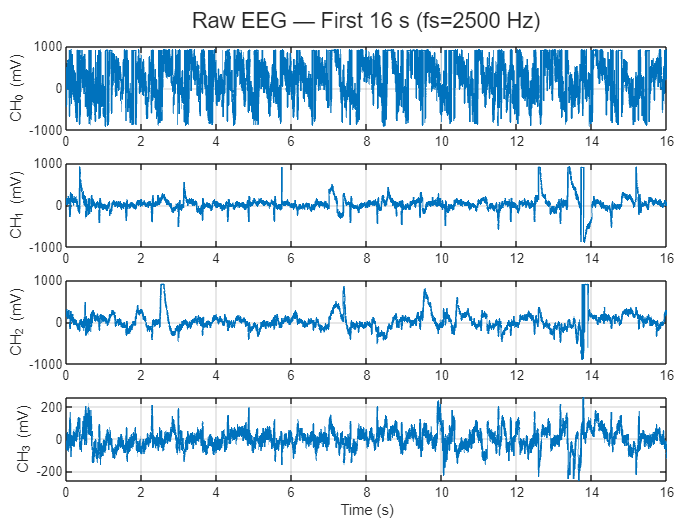

clear; close all; clc

S  = load("5df6a5cb-abcc-4fc5-b88d-79a372c648ee.mat");
x  = double(S.channelsData);          % 4 x N
fs = S.channelSampleRate;             % Hz
N  = size(x,2);

Vref = 1.8; Nb = 12;
x_mV = 1e3 * (x - 2^(Nb-1)) * (Vref / 2^Nb);

sec = 16;
M   = min(N, round(sec*fs));
t   = (0:M-1)/fs;

maxPts = 8000;
ds     = max(1, floor(M/maxPts));
tp     = (0:ds:M-1)/fs;

% ----- RAW EEG (display-decimated) -----
figure("Color","w","Name","EEG (Raw, display-decimated)");
tl = tiledlayout(4,1,"TileSpacing","compact","Padding","compact");
for ch = 1:4
    nexttile
    plot(tp, x_mV(ch,1:ds:M), "LineWidth", 1); grid on
    ylabel("CH_" + (ch-1) + " (mV)")
end
xlabel("Time (s)")
title(tl, "Raw EEG — First " + sec + " s (fs=" + fs + " Hz)")

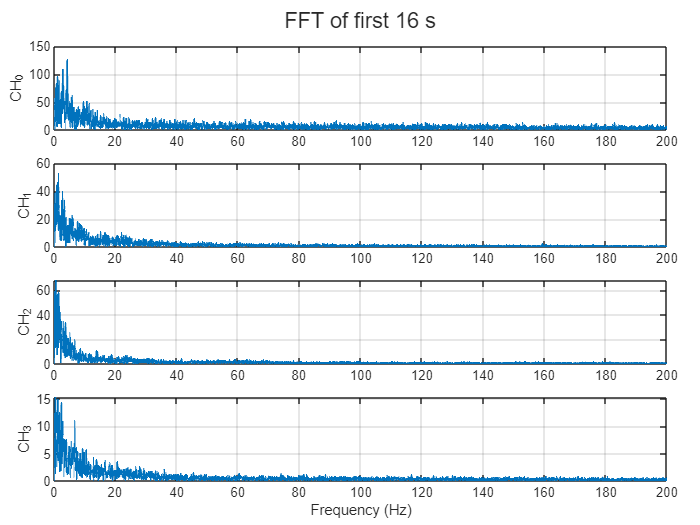


% ----- EEG FFT (single-sided) -----
Nfft = M;
f    = (0:floor(Nfft/2))*(fs/Nfft);

figure("Color","w","Name","EEG FFT (single-sided)");
tl2 = tiledlayout(4,1,"TileSpacing","compact","Padding","compact");
for ch = 1:4
    y = x_mV(ch,1:M) - mean(x_mV(ch,1:M));
    Y = fft(y, Nfft);

    P = abs(Y)/Nfft;
    P = 2*P(1:floor(Nfft/2)+1);
    P(1) = P(1)/2; if mod(Nfft,2)==0, P(end)=P(end)/2; end

    nexttile
    plot(f, P, "LineWidth", 1); grid on
    xlim([0 200])
    ylabel("CH_" + (ch-1))
end
xlabel("Frequency (Hz)")
title(tl2, "FFT of first " + sec + " s")

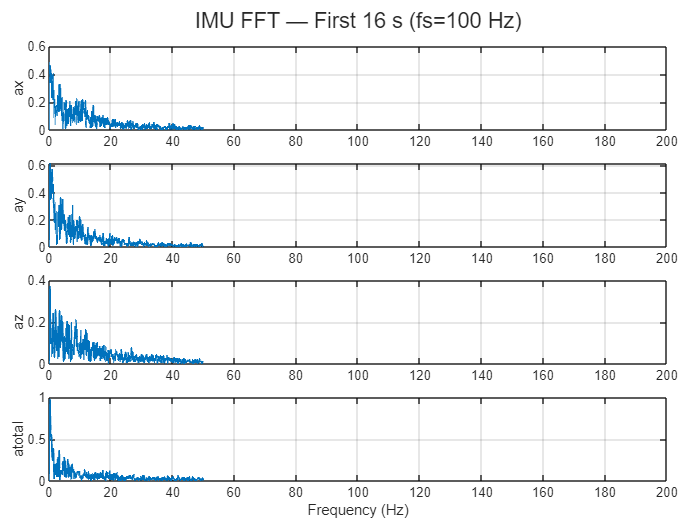


% ----- Load IMU CSV -----
T    = readtable("2025.09.13.13.46.47_Rec_2.csv");
vars = lower(string(T.Properties.VariableNames));

it = find(contains(vars,"time") | vars=="t", 1);
ix = find(contains(vars,"ax")   | contains(vars,"accx"), 1);
iy = find(contains(vars,"ay")   | contains(vars,"accy"), 1);
iz = find(contains(vars,"az")   | contains(vars,"accz"), 1);
ia = find(contains(vars,"atotal") | contains(vars,"a_total") | contains(vars,"atot"), 1);

tcsv = T{:,it}; tcsv = tcsv(:);
if max(tcsv) > 1e3, tcsv = (tcsv - tcsv(1))/1e3; else, tcsv = tcsv - tcsv(1); end

ax = T{:,ix}; ay = T{:,iy}; az = T{:,iz};
if isempty(ia)
    at = sqrt(ax.^2 + ay.^2 + az.^2);
else
    at = T{:,ia};
end

[tcsv, ord] = sort(tcsv);
ax = ax(ord); ay = ay(ord); az = az(ord); at = at(ord);
[tcsv, iu] = unique(tcsv, "stable");
ax = ax(iu); ay = ay(iu); az = az(iu); at = at(iu);

ax_i = interp1(tcsv, ax, t(:), "linear", "extrap");
ay_i = interp1(tcsv, ay, t(:), "linear", "extrap");
az_i = interp1(tcsv, az, t(:), "linear", "extrap");
at_i = interp1(tcsv, at, t(:), "linear", "extrap");

% ----- IMU FFT -----
secIMU = 16;
fs_imu = 1/median(diff(tcsv));
Mimu   = min(numel(tcsv), round(secIMU*fs_imu));
fimu   = (0:floor(Mimu/2))*(fs_imu/Mimu);

U = [ax(1:Mimu) ay(1:Mimu) az(1:Mimu) at(1:Mimu)].';
U = U - mean(U,2);

figure("Color","w","Name","IMU FFT (single-sided)");
tl4 = tiledlayout(4,1,"TileSpacing","compact","Padding","compact");
labs = ["ax" "ay" "az" "atotal"];
for k = 1:4
    Y = fft(U(k,:), Mimu);
    P = abs(Y)/Mimu;
    P = 2*P(1:floor(Mimu/2)+1);
    P(1) = P(1)/2; if mod(Mimu,2)==0, P(end)=P(end)/2; end

    nexttile
    plot(fimu, P, "LineWidth", 1); grid on
    xlim([0 200])
    ylabel(labs(k))
end
xlabel("Frequency (Hz)")
title(tl4, "IMU FFT — First " + secIMU + " s (fs=" + round(fs_imu,2) + " Hz)")

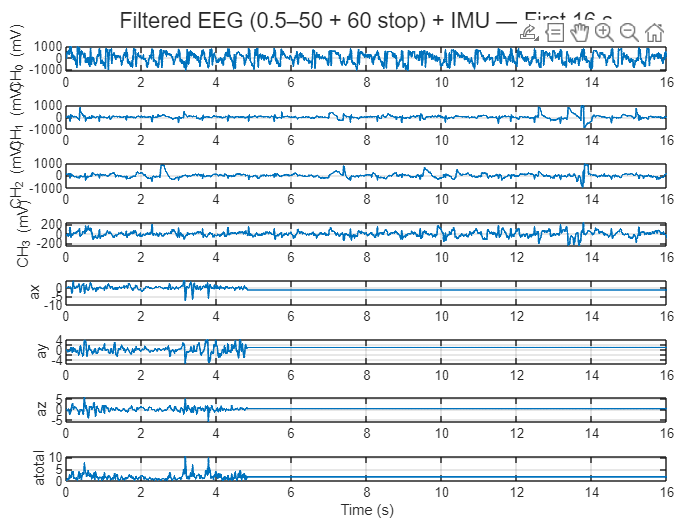


% ----- FILTER EEG (0.5–50 + 60 bandstop) -----
Xeeg = double(x_mV);
for ch = 1:4
    y = Xeeg(ch,:);
    bad = ~isfinite(y);
    if any(bad)
        i = find(~bad);
        y(bad) = interp1(i, y(i), find(bad), "linear", "extrap");
    end
    Xeeg(ch,:) = y - mean(y);
end

[z,p,k] = butter(2, 0.5/(fs/2), "high"); [sosHP,gHP] = zp2sos(z,p,k); sosHP(1,1:3) = sosHP(1,1:3)*gHP;
[z,p,k] = butter(4, 50/(fs/2),  "low");  [sosLP,gLP] = zp2sos(z,p,k); sosLP(1,1:3) = sosLP(1,1:3)*gLP;
[bBS,aBS] = butter(2, [59 61]/(fs/2), "stop");  % (if you want 50Hz mains: [49 51])

x_f = zeros(size(Xeeg));
for ch = 1:4
    y = Xeeg(ch,:);
    for s = 1:size(sosHP,1), y = filtfilt(sosHP(s,1:3), sosHP(s,4:6), y); end
    for s = 1:size(sosLP,1), y = filtfilt(sosLP(s,1:3), sosLP(s,4:6), y); end
    y = filtfilt(bBS, aBS, y);
    x_f(ch,:) = y;
end

% ----- FILTERED EEG + IMU (same figure, display-decimated) -----
figure("Color","w","Name","Filtered EEG + IMU (display-decimated)");
tl5 = tiledlayout(8,1,"TileSpacing","compact","Padding","compact");

for ch = 1:4
    nexttile
    plot(tp, x_f(ch,1:ds:M), "LineWidth", 1); grid on
    ylabel("CH_" + (ch-1) + " (mV)")
end
nexttile; plot(tp, ax_i(1:ds:M), "LineWidth", 1); grid on; ylabel("ax")
nexttile; plot(tp, ay_i(1:ds:M), "LineWidth", 1); grid on; ylabel("ay")
nexttile; plot(tp, az_i(1:ds:M), "LineWidth", 1); grid on; ylabel("az")
nexttile; plot(tp, at_i(1:ds:M), "LineWidth", 1); grid on; ylabel("atotal")

xlabel("Time (s)")
title(tl5, "Filtered EEG (0.5–50 + 60 stop) + IMU — First " + sec + " s")

drawnow limitrate

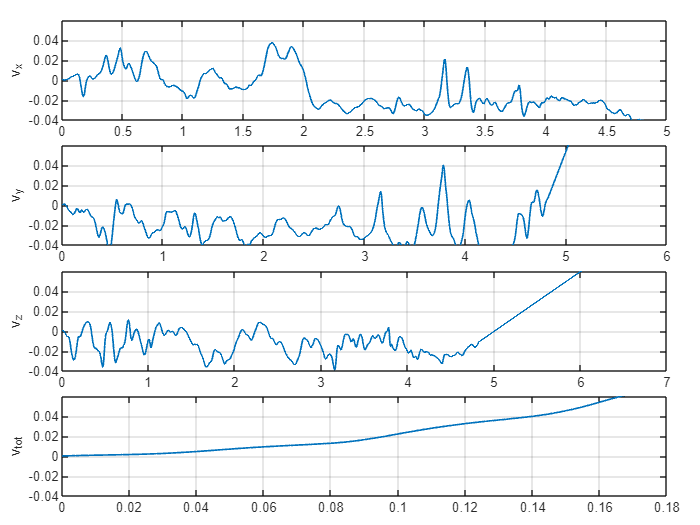

figure("Color","w");
tl = tiledlayout(4,1,"TileSpacing","compact","Padding","compact");

yl = [-0.04 0.06];

Mimu = min([M, numel(vx), numel(vy), numel(vz), numel(vt)]);
iimu = 1:ds:Mimu;

nexttile(tl); plot(tp(1:numel(iimu)), vx(iimu), "LineWidth", 1); grid on; ylabel("v_x");     ylim(yl)
nexttile(tl); plot(tp(1:numel(iimu)), vy(iimu), "LineWidth", 1); grid on; ylabel("v_y");     ylim(yl)
nexttile(tl); plot(tp(1:numel(iimu)), vz(iimu), "LineWidth", 1); grid on; ylabel("v_z");     ylim(yl)
nexttile(tl); plot(tp(1:numel(iimu)), vt(iimu), "LineWidth", 1); grid on; ylabel("v_{tot}"); ylim(yl)

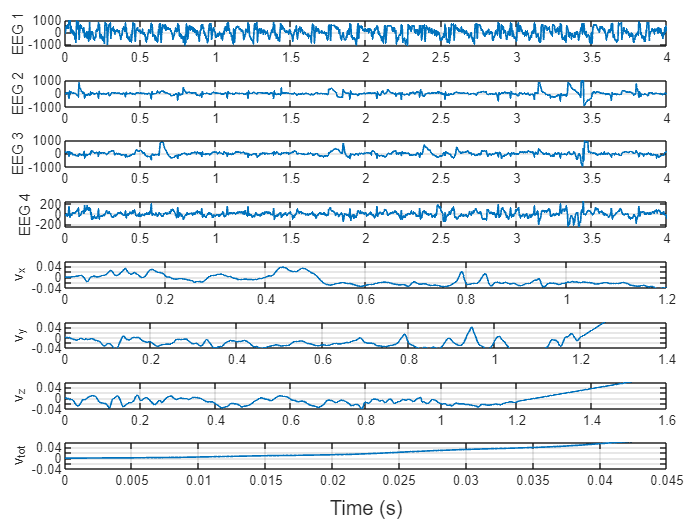


fs = 10000;
sec = 5;

M = min([ round(sec*fs), ...
          size(x_f,2), ...
          numel(ax_i), numel(ay_i), numel(az_i), numel(at_i) ]);

t = (0:M-1)/fs;

dt = 1/fs;
vx = dt * cumtrapz(ax_i(1:M));
vy = dt * cumtrapz(ay_i(1:M));
vz = dt * cumtrapz(az_i(1:M));
vt = dt * cumtrapz(at_i(1:M));

figure("Color","w");
tl = tiledlayout(8,1,"TileSpacing","compact","Padding","compact");

for ch = 1:4
    nexttile(tl);
    plot(t, x_f(ch,1:M), "LineWidth", 1); grid on
    ylabel("EEG " + ch)
end

yl = [-0.04 0.06];
nexttile(tl); plot(t, vx, "LineWidth", 1); grid on; ylabel("v_x");     ylim(yl)
nexttile(tl); plot(t, vy, "LineWidth", 1); grid on; ylabel("v_y");     ylim(yl)
nexttile(tl); plot(t, vz, "LineWidth", 1); grid on; ylabel("v_z");     ylim(yl)
nexttile(tl); plot(t, vt, "LineWidth", 1); grid on; ylabel("v_{tot}"); ylim(yl)

xlabel(tl, "Time (s)");

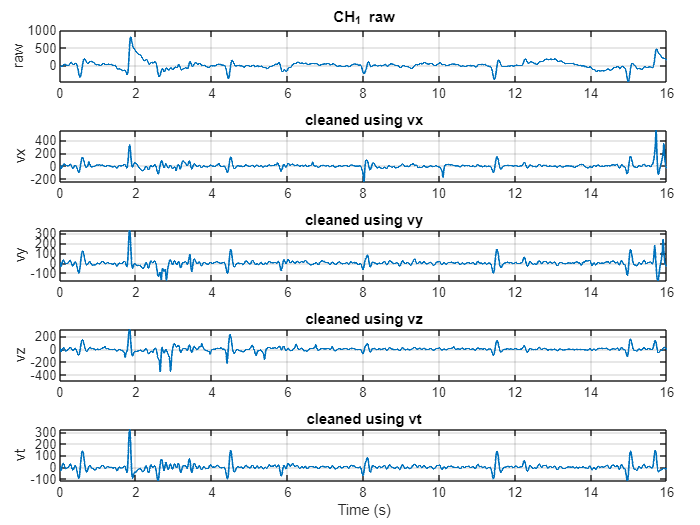

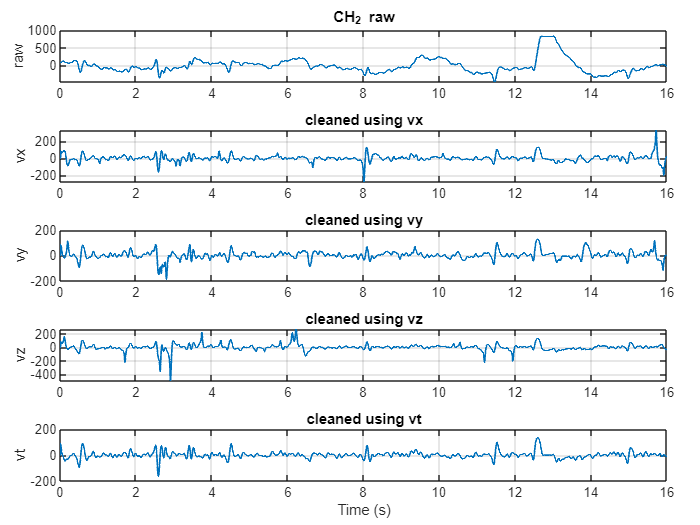

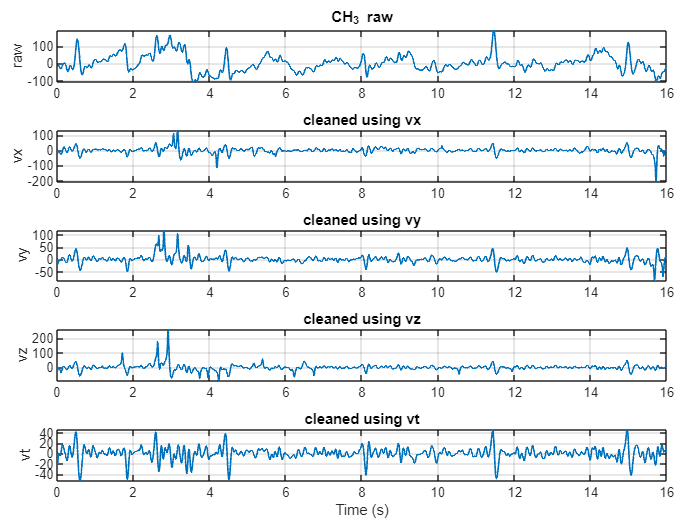



L = 9;
mu = 0.1;
eps0 = 1e-6;

V = {vx(:), vy(:), vz(:), vt(:)};
Vname = ["vx","vy","vz","vt"];

N = min([size(x_f,2), numel(vx), numel(vy), numel(vz), numel(vt), numel(tp)]);
tp = tp(1:N);
S  = double(x_f(:,1:N)).';   % [N x 4]


E = zeros(N, 4, 4);            % cleaned:   [time x ch x ref]
Y = zeros(N, 4, 4);            % estimated: [time x ch x ref]

for r = 1:4
    m = V{r}(1:N);
    for ch = 1:4
        [e,y] = nlms1(S(:,ch), m, L, mu, eps0);
        E(:,ch,r) = e;
        Y(:,ch,r) = y;
    end
end

for ch = 1:4
    figure("Color","w","Name","CH_" + (ch-1) + " (raw + NLMS per IMU)");
    tl = tiledlayout(5,1,"TileSpacing","compact","Padding","compact");

    % 1) Raw (top)
    nexttile(tl);
    plot(tp, S(:,ch), "LineWidth", 1); grid on
    ylabel("raw"); title("CH_" + (ch-1) + " raw")

    % 2–5) Cleaned separately for each IMU velocity
    for r = 1:4
        nexttile(tl);
        plot(tp, E(:,ch,r), "LineWidth", 1); grid on
        ylabel(Vname(r))
        if r==4, xlabel("Time (s)"); end
        title("cleaned using " + Vname(r))
    end
end

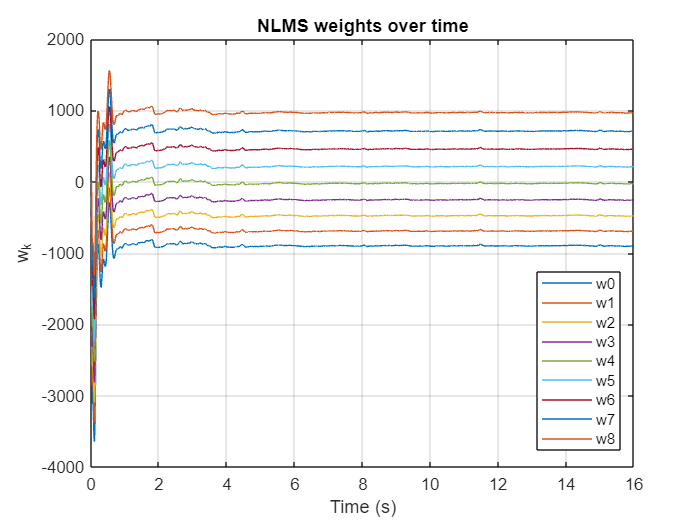

[e,y,w,W] = nlms1(S(:,ch), V{r}(1:N), L, mu, eps0);

tW = tp(1:size(W,2));
figure("Color","w");
plot(tW, W.'); grid on
xlabel("Time (s)"); ylabel("w_k")
title("NLMS weights over time")
legend("w0","w1","w2","w3","w4","w5","w6","w7","w8","Location","best")

function [e,y,w,W] = nlms1(s, m, L, mu, eps0)
s = s(:); m = m(:);
N = min(numel(s), numel(m));
s = s(1:N); m = m(1:N);

w = zeros(L,1);
y = zeros(N,1);
e = zeros(N,1);
W = zeros(L,N);

for n = L:N
    x = m(n:-1:n-L+1);
    y(n) = w.'*x;                                % <-- FIXED
    e(n) = s(n) - y(n);
    w = w + (mu/(eps0 + x.'*x)) * x * e(n);
    W(:,n) = w;
end
end
